## MATLAB大作业

clear; clc;
format long

## 第一部分：数据导入与可视化

path_users = './data/Foursquare/users.csv';
path_tips = './data/Foursquare/tips.csv';
path_friends = './data/Foursquare/friends.csv';
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';
% users = readtable(path_users); tips = readtable(path_tips); friends = readtable(path_friends);
% country = readtable(path_country); daily = readtable(path_country)

% US Daily New Cases Example
DIO = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', { ...
            'new_vaccinations', 'double'; ...
            'total_vaccinations', 'double' ...
            }...
        } ...
    ).DetectImport.DetectedImportOptions;
[DIO.VariableNames', DIO.VariableTypes']

ans = 13×2 cell array
    {'location'          }    {'char'    }
    {'continent'         }    {'char'    }
    {'date'              }    {'datetime'}
    {'new_cases'         }    {'double'  }
    {'total_cases'       }    {'double'  }
    {'new_tests'         }    {'double'  }
    {'total_tests'       }    {'double'  }
    {'positive_rate'     }    {'double'  }
    {'new_vaccinations'  }    {'double'  }
    {'total_vaccinations'}    {'double'  }
    {'hosp_patients'     }    {'double'  }
    {'icu_patients'      }    {'double'  }
    {'stringency_index'  }    {'double'  }

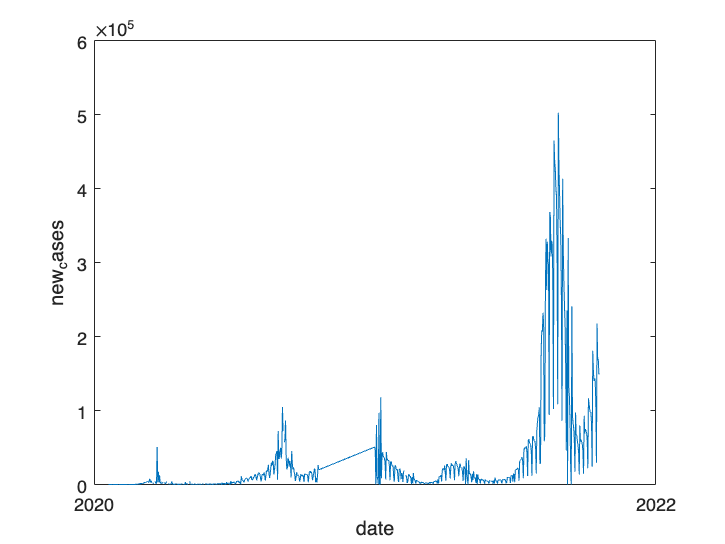

[~, ~, FirstLast] = selecttable( ...
    StatisticsAnalysis( ... Table Import
            'TablePath', path_daily, ...
            'DetectedImportOptions', DIO, ...
            'ImportOptions', {'SelectedVariableNames', {'location', 'date'} } ...
        ).ImportTable, ...
    { ... Table Selection
        'location', 'France'; ... Country
        'date', { ...
            arange(datetime('2020-01-01'), datetime('2020-12-31')); ...
            arange(datetime('2021-04-01'), datetime('2022-04-01')) ...
            } ... Time Range
        } ...
    );
USDaily2021 = StatisticsAnalysis( ... Table Import
    'TablePath', path_daily, ...
    'DetectedImportOptions', DIO, ...
    'ImportOptions', { ...
        'DataLines', {FirstLast}; ... 
        'SelectedVariableNames', {'date', 'new_cases', 'new_vaccinations'}...
        }...
    ).TagsGenerate( ... Continuity Tag and Properties Addition
        'CustomTagName', {'sexy', [0 1 1]; 'dance', [1 0 0]}, ...
        'TagContinuity', [0 1 1] ...
    ).addProp;
usdaily21 = table2timetable(USDaily2021);
figure(1); plot(usdaily21, 'new_cases'); datetick x;

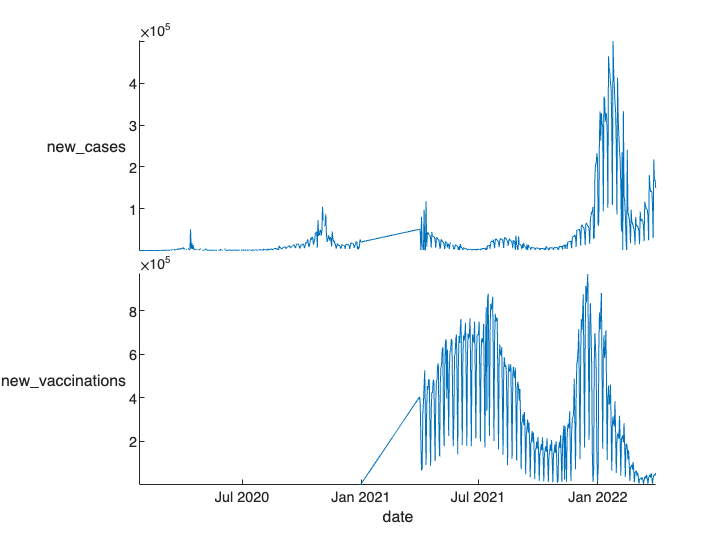

figure(2); stackedplot(usdaily21);

usdaily21.Properties

ans =   TimetableProperties with properties:
               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [709×1 datetime]
                 StartTime: 2020-01-24
                SampleRate: NaN
                  TimeStep: NaN
   Custom Properties (access using t.Properties.CustomProperties.<name>):
     DetectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [14×3 table]
                      Size: [709 3]
                  TagNames: {{2×1 cell}  {2×1 cell}}
               UniqueCount: {[659]  [370]}
                ValueClass: {'double'  'double'}
              MissingCount: {[10]  [339]}
              MissingRatio: {[0.014

## 第二部分：数据处理

% Preserve Original Tags
StatisticsAnalysis('Table', USDaily2021).TagsGenerate.addProp.Properties

ans =   TableProperties with properties:
               Description: ''
                  UserData: []
            DimensionNames: {'Row'  'Variables'}
             VariableNames: {'date'  'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowNames: {}
   Custom Properties (access using t.Properties.CustomProperties.<name>):
     DetectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [14×3 table]
                      Size: [709 3]
                  TagNames: {{2×1 cell}  {2×1 cell}  {2×1 cell}}
               UniqueCount: {[709]  [659]  [370]}
                ValueClass: {'datetime'  'double'  'double'}
              MissingCount: {[0]  [10]  [339]}
              MissingRatio: {[0]  [0.014104372355430]  [0.478138222849083]}
    LogicalRatioFirstValue: {[]  []  []}


% Custom Tag Function
StatisticsAnalysis('Table', USDaily2021).TagsGenerate( ...
    'TagContinuity', [0 1 1], ...
    'CustomTagFunction', { ...
        'sexy', 'SexyVariance', @(x,y)tsnanvar(x{:,:})/2; ...
        'dance', 'DancingRaio', @(x,y)'p' ...
        } ...
    ).addProp.Properties

ans =   TableProperties with properties:
               Description: ''
                  UserData: []
            DimensionNames: {'Row'  'Variables'}
             VariableNames: {'date'  'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowNames: {}
   Custom Properties (access using t.Properties.CustomProperties.<name>):
     DetectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [709 3]
                  TagNames: {{2×1 cell}  {2×1 cell}  {2×1 cell}}
               UniqueCount: {[709]  [659]  [370]}
                ValueClass: {'datetime'  'double'  'double'}
              MissingCount: {[0]  [10]  [339]}
              MissingRatio: {[0]  [0.014104372355430]  [0.478138222849083]}
    LogicalRatioFirstValue: {[]  []  []}


% Custom Tag Function (One Tag Generate)
[~,~,temp] = StatisticsAnalysis('Table',USDaily2021).OneTagGenerate('new_vaccinations', 'TagContinuity', 1)

temp = 12×2 cell array
    {2×1 cell               }    {'TagNames'    }
    {[                  370]}    {'UniqueCount' }
    {'double'               }    {'ValueClass'  }
    {[                  339]}    {'MissingCount'}
    {[    0.478138222849083]}    {'MissingRatio'}
    {[                  369]}    {'Min'         }
    {[               970144]}    {'Max'         }
    {[3.518466108108108e+05]}    {'Mean'        }
    {[               291937]}    {'Median'      }
    {[                  369]}    {'Mode'        }
    {[6.422557538565301e+10]}    {'Variance'    }
    {'new_vaccinations'     }    {'VariableName'}

selecttable(USDaily2021, {'date', datetime('2020-01-24')}).Properties.CustomProperties.Tags

ans = 2×3 table
                      date        new_cases     new_vaccinations
                  ____________    __________    ________________
    TagNames      {2×1 cell  }    {2×1 cell}       {2×1 cell}   
    ValueClass    {'datetime'}    {'double'}       {'double'}   